clc;
clear;
close all;

%% =========================================================
% TECHNO-ECONOMIC ANALYSIS OF RENEWABLE ENERGY BASED
% EV CHARGING STATION
%% =========================================================

%% ================= STYLE SETTINGS =================

set(0,'DefaultFigureColor','w');
set(0,'DefaultAxesFontName','Times New Roman');
set(0,'DefaultAxesFontSize',11);
set(0,'DefaultLineLineWidth',2);

%% ================= PARAMETERS =================

% Solar Parameters
Solar_Irradiance = 1000;      % W/m²
PV_eff = 0.20;
PV_Area = 180;               % Increased for higher solar share
T_ambient = 30;

% Wind Parameters
Wind_Speed = 7;
Air_Density = 1.225;
Cp = 0.30;
Rotor_Radius = 3.0;
Rotor_Area = pi*(Rotor_Radius^2);

% EV Charging Load
EV_Load_Rating = 7;          % kW

% Battery Parameters
Battery_Capacity = 150;      % kWh
eta_ch = 0.95;
eta_dis = 0.93;

% Converter Efficiency
inverter_eff = 0.97;
converter_eff = 0.98;

%% ================= ECONOMIC PARAMETERS =================

capital_cost = 3500000;       % Rs
grid_cost = 13;              % Rs/kWh
export_price = 4.5;            % Rs/kWh

years = 25;

%% ================= TIME VECTOR =================

t = 1:168;                   % 7 Days
h = mod(t-1,24);

%% ================= SOLAR MODEL =================

temp_loss = 1 - 0.004*(T_ambient-25);

solar = Solar_Irradiance .* ...
        PV_eff .* ...
        PV_Area .* ...
        max(0,sin(pi*(h-6)/12)) .* ...
        temp_loss;

solar = solar/1000;

%% ================= WIND MODEL =================

rng(2);

Wind_Profile = Wind_Speed + ...
               0.8*sin(0.12*t) + ...
               0.4*randn(size(t));

Wind_Profile(Wind_Profile<0)=0;

wind = 0.5 .* ...
       Air_Density .* ...
       Rotor_Area .* ...
       (Wind_Profile.^3) .* ...
       Cp;

wind = wind/1000;

%% ================= EV LOAD MODEL =================

morning_peak = 2*exp(-((h-9).^2)/8);

evening_peak = 4*exp(-((h-19).^2)/10);

load_ev = EV_Load_Rating + ...
          morning_peak + ...
          evening_peak;

rng(1);

load_ev = load_ev .* ...
         (0.96 + 0.08*rand(size(load_ev)));

%% ================= RENEWABLE POWER =================

renewable = (solar + wind) .* ...
            inverter_eff .* ...
            converter_eff;

%% ================= BATTERY STORAGE =================

soc = zeros(size(t));
soc(1)=80;

battery = zeros(size(t));

grid_import = zeros(size(t));
grid_export = zeros(size(t));

for i=2:length(t)

    net = renewable(i)-load_ev(i);

    if net > 0

        available_capacity = ...
            ((90-soc(i-1))/100)*Battery_Capacity;

        charge = min(net,available_capacity);

        battery(i)=charge;

        soc(i)=soc(i-1)+ ...
            (charge*eta_ch/Battery_Capacity)*100;

        grid_export(i)=max(net-charge,0);

    else

        deficit = abs(net);

        available_energy = ...
            ((soc(i-1)-25)/100)*Battery_Capacity;

        discharge = ...
            min(deficit,available_energy);

        battery(i)=-discharge;

        soc(i)=soc(i-1)- ...
            (discharge/(Battery_Capacity*eta_dis))*100;

        grid_import(i)= ...
            max(deficit-discharge,0);

    end

    soc(i)=max(25,min(90,soc(i)));

end

%% ================= ENERGY CALCULATIONS =================

total_load = sum(load_ev);

solar_energy = sum(solar);

wind_energy = sum(wind);

grid_energy = sum(grid_import);

export_energy = sum(grid_export);

total_generation = solar_energy + wind_energy;

solar_share = ...
    (solar_energy/total_generation)*100;

wind_share = ...
    (wind_energy/total_generation)*100;

grid_share = ...
    (grid_energy/total_load)*100;

%% ================= ECONOMIC ANALYSIS =================

annual_grid_cost = ...
    grid_energy * grid_cost * 52;

annual_export_income = ...
    export_energy * export_price * 52;

annual_saving = ...
    ((total_load-grid_energy) ...
    * grid_cost * 52);

net_annual_benefit = ...
    annual_saving + annual_export_income;

payback = ...
    capital_cost / net_annual_benefit;

LCOE = ...
   (capital_cost + ...
   (annual_grid_cost*years)) / ...
   (total_load*52*years);

TNPC = ...
    capital_cost + ...
    (annual_grid_cost*years);

%% ================= CO2 ANALYSIS =================

emission_grid = 0.82;

co2_without_RE = ...
    total_load * emission_grid;

co2_with_RE = ...
    grid_energy * emission_grid;

co2_saved = ...
    co2_without_RE - co2_with_RE;

%% ================= KPI TABLE =================

KPI = table( ...
    LCOE,...
    TNPC,...
    payback,...
    solar_share,...
    wind_share,...
    grid_share);

disp(KPI);

     LCOE        TNPC       payback    solar_share    wind_share    grid_share
    ______    __________    _______    ___________    __________    __________

    1.9341    3.5159e+06    3.1998       86.027         13.973       0.067462 



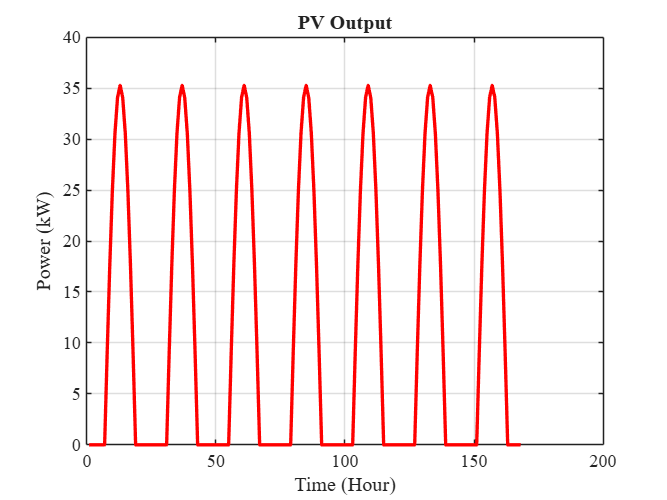


%% =====================================================
%% GRAPH 1 : SOLAR OUTPUT
%% =====================================================

figure;
plot(t,solar,'r');
grid on;

title('PV Output');
xlabel('Time (Hour)');
ylabel('Power (kW)');

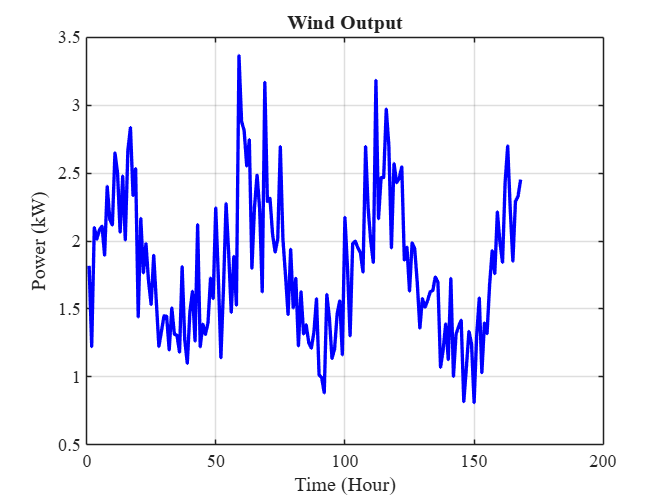


%% =====================================================
%% GRAPH 2 : WIND OUTPUT
%% =====================================================

figure;
plot(t,wind,'b');
grid on;

title('Wind Output');
xlabel('Time (Hour)');
ylabel('Power (kW)');

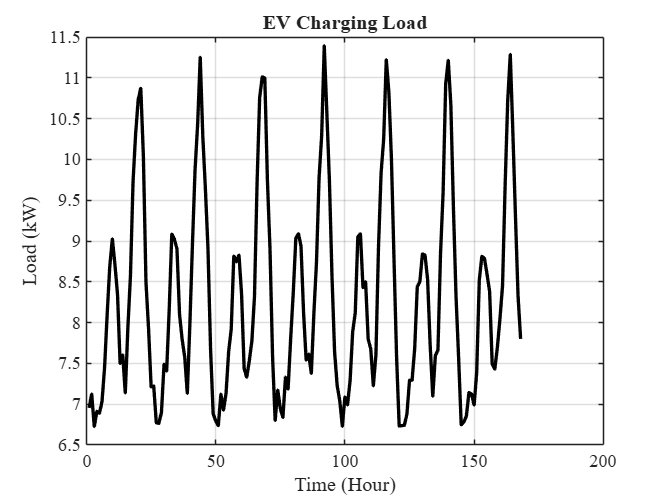


%% =====================================================
%% GRAPH 3 : EV LOAD
%% =====================================================

figure;
plot(t,load_ev,'k');
grid on;

title('EV Charging Load');
xlabel('Time (Hour)');
ylabel('Load (kW)');

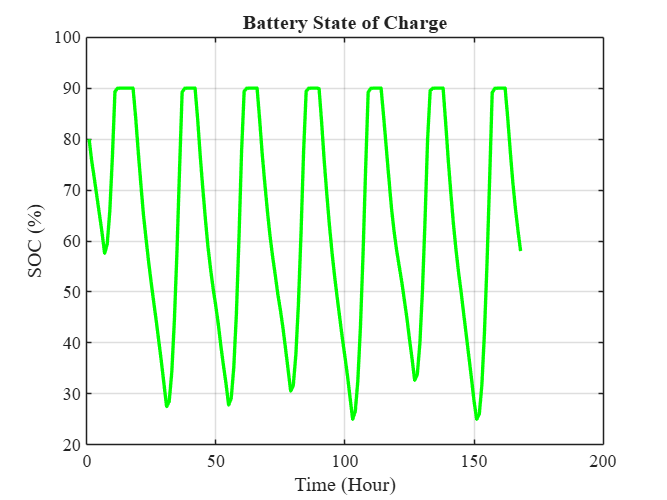


%% =====================================================
%% GRAPH 4 : BATTERY SOC
%% =====================================================

figure;
plot(t,soc,'g');
grid on;

ylim([20 100]);

title('Battery State of Charge');
xlabel('Time (Hour)');
ylabel('SOC (%)');

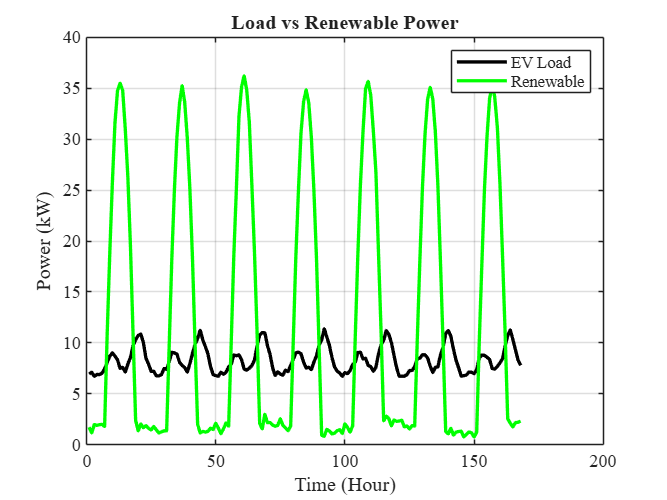


%% =====================================================
%% GRAPH 5 : LOAD VS RENEWABLE
%% =====================================================

figure;

plot(t,load_ev,'k');
hold on;

plot(t,renewable,'g');

grid on;

legend('EV Load','Renewable');

title('Load vs Renewable Power');

xlabel('Time (Hour)');
ylabel('Power (kW)');

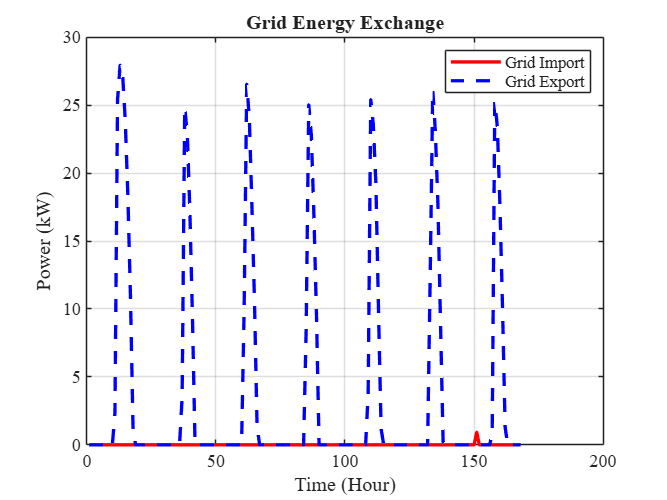


%% =====================================================
%% GRAPH 6 : GRID IMPORT EXPORT
%% =====================================================

figure;

plot(t,grid_import,'r');
hold on;

plot(t,grid_export,'b--');

grid on;

legend('Grid Import','Grid Export');

title('Grid Energy Exchange');

xlabel('Time (Hour)');
ylabel('Power (kW)');

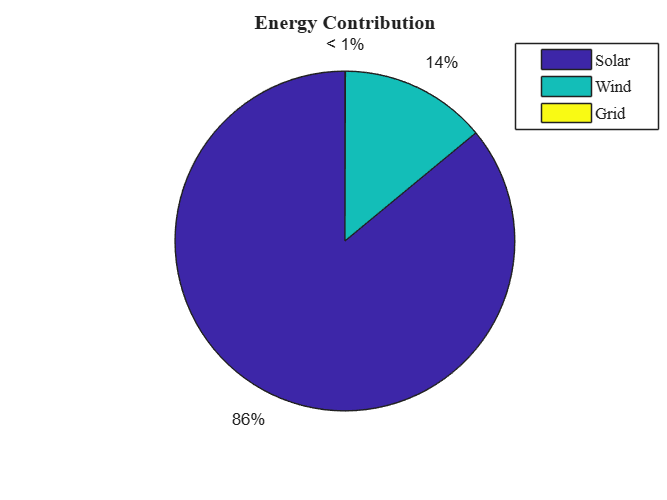


%% =====================================================
%% GRAPH 7 : ENERGY CONTRIBUTION
%% =====================================================

figure;

energy_mix = [ ...
    solar_energy ...
    wind_energy ...
    max(grid_energy,0.01)];

pie(energy_mix);

title('Energy Contribution');

legend(["Solar", "Wind", "Grid"], "Position", [0.7785 0.7460 0.2037, 0.1625])

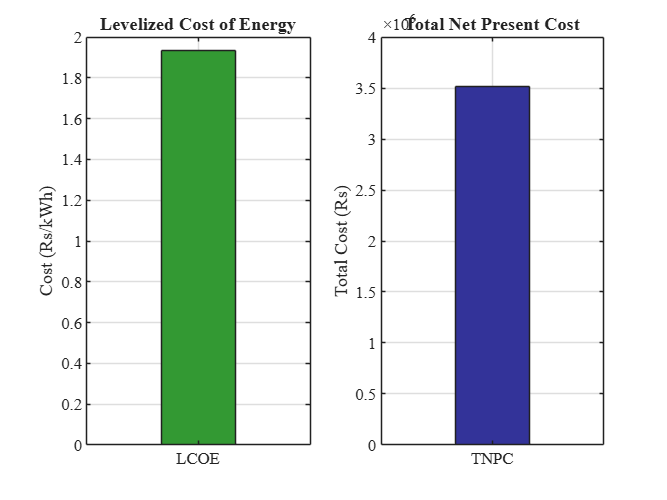


%% =====================================================
%% GRAPH 8 : ECONOMIC ANALYSIS (IMPROVED VIEW)
%% =====================================================

figure;
subplot(1,2,1);
bar(LCOE, 'FaceColor', [0.2 0.6 0.2]);
grid on;
title('Levelized Cost of Energy');
ylabel('Cost (Rs/kWh)');
set(gca, 'XTickLabel', {'LCOE'});

subplot(1,2,2);
bar(TNPC, 'FaceColor', [0.2 0.2 0.6]); 
grid on;
title('Total Net Present Cost');
ylabel('Total Cost (Rs)');
set(gca, 'XTickLabel', {'TNPC'});

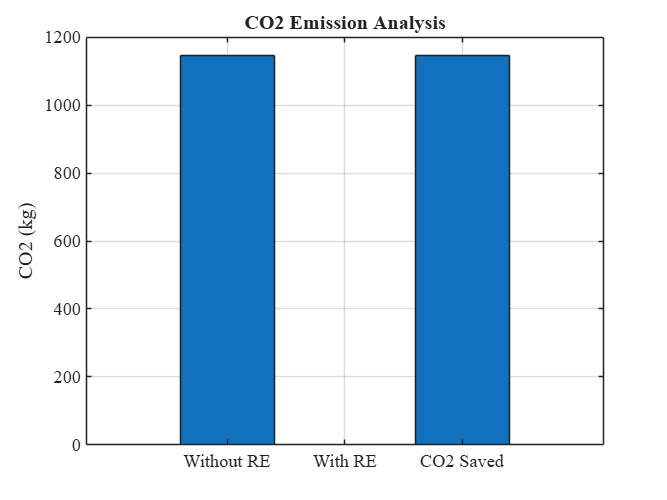


%% =====================================================
%% GRAPH 9 : CO2 ANALYSIS
%% =====================================================

figure;

bar([co2_without_RE co2_with_RE co2_saved]);

set(gca,'XTickLabel',...
    {'Without RE','With RE','CO2 Saved'});

title('CO2 Emission Analysis');

ylabel('CO2 (kg)');

grid on;


%% ================= FINAL RESULTS =================

fprintf('\n=====================================\n');

fprintf('FINAL RESULTS\n');

FINAL RESULTS


fprintf('=====================================\n');


fprintf('\nTotal Load = %.2f kWh\n',total_load);


Total Load = 1398.33 kWh



fprintf('Solar Energy = %.2f kWh\n',solar_energy);

Solar Energy = 1875.85 kWh



fprintf('Wind Energy = %.2f kWh\n',wind_energy);

Wind Energy = 304.69 kWh



fprintf('Grid Energy = %.2f kWh\n',grid_energy);

Grid Energy = 0.94 kWh



fprintf('Export Energy = %.2f kWh\n',export_energy);

Export Energy = 637.52 kWh



fprintf('\nSolar Share = %.2f %%\n',solar_share);


Solar Share = 86.03 %



fprintf('Wind Share = %.2f %%\n',wind_share);

Wind Share = 13.97 %



fprintf('Grid Share = %.2f %%\n',grid_share);

Grid Share = 0.07 %



fprintf('\nLCOE = %.2f Rs/kWh\n',LCOE);


LCOE = 1.93 Rs/kWh



fprintf('TNPC = %.2f Rs\n',TNPC);

TNPC = 3515942.54 Rs



fprintf('Payback Period = %.2f Years\n',payback);

Payback Period = 3.20 Years



fprintf('\nCO2 Saved = %.2f kg\n',co2_saved);


CO2 Saved = 1145.85 kg



fprintf('\nFinal Battery SOC = %.2f %%\n',soc(end));


Final Battery SOC = 58.02 %



fprintf('\n=====================================\n');